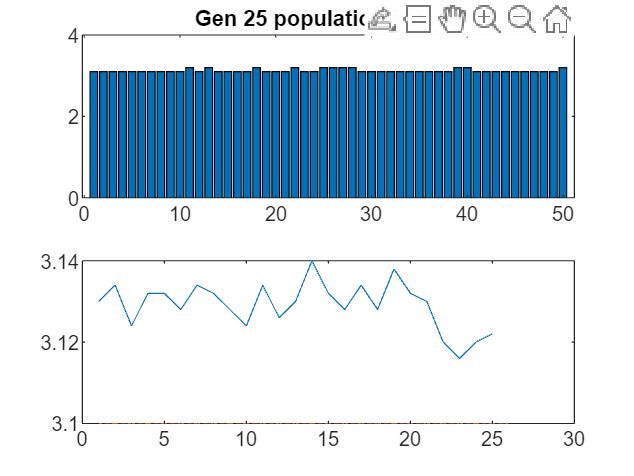

close all;
clear;
rng default;

wdist = 0.3;
wcong = 0.3;
wturn = 0;
falseOrdered
layout = "l1";
start = 1;
goal =  [10, 20, 30, 40, 50];

  


prob = getAdjDigraphCoords(layout, start, goal);
prob.interval = 0.;
prob.postProcessFcn = @postProcessUnordered;
costAdj = wdist * prob.adj + wcong * prob.occupancy;
% Cost matrix needed for pair-wise shortest distances between nodes
costMatrix = distances(digraph(costAdj));

% The fitness function measures how good a candidate solution is. That is,
% the ordering of stop points
fitness = @(sol) sum(costMatrix(sub2ind([prob.N, prob.N], sol(1:end-1), sol(2:end))));
% The local fitness function is the cost of individual paths between two
% stop points. This is the same as fitness in ordered GA
prob.fitness_local = @(sol) costFunc(sol, prob.adj, prob.start, prob.goal, prob.coords, prob.occupancy, 0, wdist, wturn, wcong);
%%

% optimiztion options
opts = optimoptions( ...
    'ga', ...
    'SelectionFcn',@selectionFunc,...
    'CrossoverFraction', 0.75,...
    'CrossoverFcn',@crossoverFuncUnordered,...
    'MutationFcn',@mutationFuncUnordered,...
    'PopulationSize',50,...
    'CreationFcn',@creationFuncUnordered,...
    'EliteCount',10,...,
    'MaxStallGenerations',max(100, length(prob.adj)^2),...
    'FunctionTolerance',0,...
    'MaxGenerations', 25);

[stops, cost, timeTaken, prob] = GAVariable(opts, prob, fitness);



disp("Best solution: "); disp(stops);

Best solution: 
     1    20    30    40    10    50



disp("Best fitness: "); disp(cost);

Best fitness: 
    3.1000



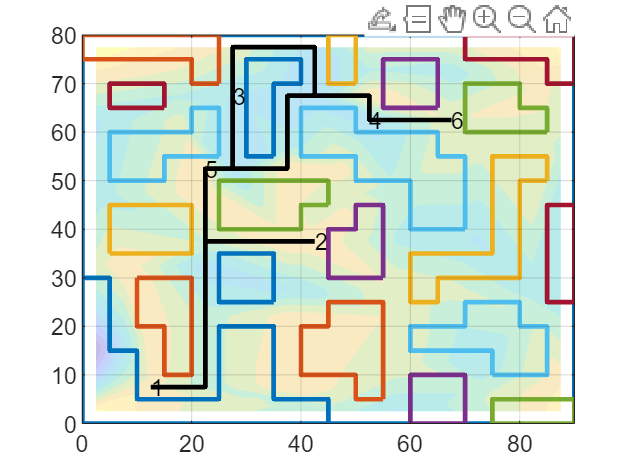

delete(prob.lines);
hold(prob.axMap, 'on');
for i=1:length(stops)-1
    [path, ~, ~] = AStar(stops(i), stops(i+1), prob.fitness_local, prob.adj);
    % highlight(prob.pl, path(1:end-1), path(2:end), 'EdgeColor','black', 'NodeColor','black');
    plot(prob.axMap, prob.coords(path,1), prob.coords(path,2), 'Color','black', 'LineWidth', 2);
    text(prob.axMap, prob.coords(stops(i),1), prob.coords(stops(i),2), num2str(i));
end
text(prob.axMap, prob.coords(stops(end),1), prob.coords(stops(end),2), num2str(length(stops)));
hold(prob.axMap, 'off');

%%